# Parameters

m_c = 1.5;
m_p = 0.5;
g = 9.82;
L = 1;
d_1 = 0.01;
d_2 = 0.01;

# Task 1.1

# Creating state space model


$$\dot{x} = Ax + Bu \\
y=Cx +Du$$



A = [0 0 1 0; 0 0 0 1];
A(3,1) = 0;
A(3,2) = g*m_p/m_c;
A(3,3) = -d_1/m_c;
A(3,4) = -d_2/(L*m_c);
A(4,1) = 0;
A(4,2) = g*(m_p+m_c)/(L*m_c);
A(4,3) = -d_1/(L*m_c);
A(4,4) = (-d_2*(m_c+m_p))/(L*L*m_c*m_p);

B = [0; 0; 1/m_c; 1/(L*m_c)];

C = [0 1 0 0];

D = [0];

sys = ss(A,B,C,D)

sys =
 
  A = 
              x1
   x1          0
   x2          0
   x3          0
   x4          0
 
              x2
   x1          0
   x2          0
   x3      3.273
   x4      13.09
 
              x3
   x1          1
   x2          0
   x3  -0.006667
   x4  -0.006667
 
              x4
   x1          0
   x2          1
   x3  -0.006667
   x4   -0.02667
 
  B = 
           u1
   x1       0
   x2       0
   x3  0.6667
   x4  0.6667
 
  C = 
       x1  x2  x3
   y1   0   1   0
 
       x4
   y1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



# Task 1.2

# Analyzing the state space model

p = pole(sys)

p =    -3.6327
    3.6043
   -0.0050
         0


Since all poles are not negative the system is not stable. 

s = isstable(sys)

s = logical
   0


Eigen values are same as poles. In state space domain we use the term 'eigen value' since matrices are involved. In frequrency domain we use the term 'poles' since transfer function is involved.  

e = eig(sys)

e =    -3.6327
    3.6043
   -0.0050
         0


When we represent our system in frequency domain, we will get a transfer function. Zeros implies the frequency at which the numerator of the transfer function is zero. 

z = zero(sys)

z = 	1.0e+-18 *

    0.1016
         0


Since the zero of the transfer function lies on the right half plane i.e., positive root, the system is non-minimum phase. This also implies that our system is difficult to control.    

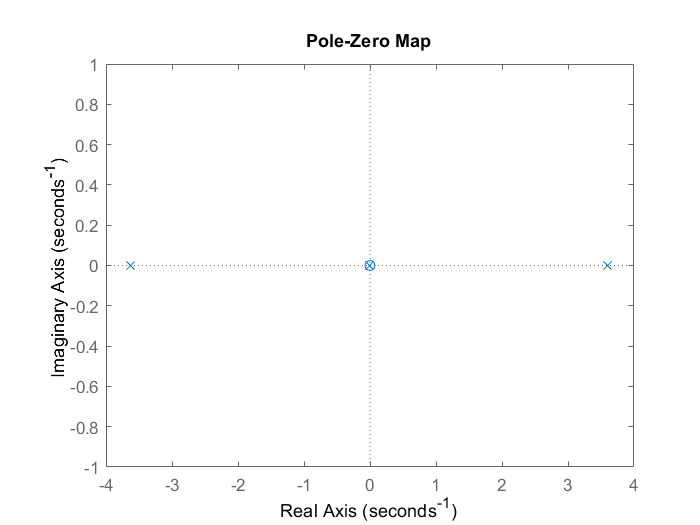

pzmap(sys)

In pole-zero map it seems that there are no zeroes(circles) on right half plane, and it can be wrongly interpreted that the system is minimal-phase. But the reason is that the zero on the right half plane is very small, due to which it is very close to origin.

# Task 1.3

# Frequency domain analysis of state space model

$G(s) = C (sI-A)^{-1}B + D$            --- Transfer function in frequency domain from state space model matrices 

s=tf('s');
G=C*(inv(s*eye(4)-A))*B + D

G =
 
                           
  0.6667 s^4 + 0.02222 s^3 
                           
          - 8.729 s^2      
                           
          - 0.04364 s      
                           
             - 9.281e-17   
                           
  -------------------------
                         
   s^6 + 0.06667 s^5     
                         
           - 26.19 s^4   
                         
           - 1.004 s^3   
                         
           + 171.4 s^2   
                         
           + 1.714 s     
                         
               + 0.004286
                         
 
Continuous-time transfer function.



G1=ss2tf(A,B,C,D);
sys2=zpk(sys)

sys2 =
 
                 
        0.66667 s
                 
  ----------------------
                        
  (s+3.633) (s-3.604)   
                        
               (s+0.005)
                        
 
Continuous-time zero/pole/gain model.

